clc; clear;


% Simulation Parameters
Pt = 1;                      % Total transmit power
N0 = 1e-9;                   % Noise power
numSymbols = 1e5;            % Number of BPSK symbols
eta = 3;                     % Path loss exponent


% Distances
d1 = 50;                     % User 1 (strong)
d2 = 200;                    % User 2 (weak)


% Sweep over power allocation for User 1 (strong)
alpha1_vals = 0.05:0.05:0.45;   % User 1 power fraction
ber1_vals = zeros(size(alpha1_vals));
ber2_vals = zeros(size(alpha1_vals));
snr1_vals = zeros(size(alpha1_vals));
snr2_vals = zeros(size(alpha1_vals));



for idx = 1:length(alpha1_vals)
    alpha1 = alpha1_vals(idx);
    alpha2 = 1 - alpha1;

    % Generate BPSK symbols
    x1 = 2*randi([0 1], 1, numSymbols) - 1;
    x2 = 2*randi([0 1], 1, numSymbols) - 1;

    % Channel fading with path loss
    h1 = (1/sqrt(2))*(randn(1, numSymbols) + 1i*randn(1, numSymbols)) / d1^(eta/2);
    h2 = (1/sqrt(2))*(randn(1, numSymbols) + 1i*randn(1, numSymbols)) / d2^(eta/2);

    % Transmitted superimposed signal
    s = sqrt(alpha1*Pt)*x1 + sqrt(alpha2*Pt)*x2;

    % Add noise
    n1 = sqrt(N0/2)*(randn(1, numSymbols) + 1i*randn(1, numSymbols));
    n2 = sqrt(N0/2)*(randn(1, numSymbols) + 1i*randn(1, numSymbols));

    % Received signals
    y1 = h1 .* s + n1;
    y2 = h2 .* s + n2;

    % Equalize
    y1_eq = y1 ./ h1;
    y2_eq = y2 ./ h2;

    % User 1 (strong) - perform SIC
    x2_hat_user1 = real(y1_eq) > 0;
    x2_reconstructed = 2*x2_hat_user1 - 1;
    s1_hat = y1_eq - sqrt(alpha2*Pt)*x2_reconstructed;
    x1_hat_user1 = real(s1_hat) > 0;
    x1_orig = (x1 + 1)/2;
    ber1_vals(idx) = sum(x1_hat_user1 ~= x1_orig) / numSymbols;

    % User 2 (weak) - decode directly
    x2_hat_user2 = real(y2_eq) > 0;
    x2_orig = (x2 + 1)/2;
    ber2_vals(idx) = sum(x2_hat_user2 ~= x2_orig) / numSymbols;

    % Estimate SNRs (mean received power / noise)
    snr1_vals(idx) = 10*log10(mean(abs(h1).^2) * alpha1 * Pt / N0);
    snr2_vals(idx) = 10*log10(mean(abs(h2).^2) * alpha2 * Pt / N0);
end


% Final Power Allocation Display
final_idx = length(alpha1_vals);
fprintf('Final Power Allocation:\n');

Final Power Allocation:


fprintf('User 1 (Strong): %.2f%%\n', alpha1_vals(final_idx)*100);

User 1 (Strong): 45.00%


fprintf('User 2 (Weak): %.2f%%\n\n', (1 - alpha1_vals(final_idx))*100);

User 2 (Weak): 55.00%



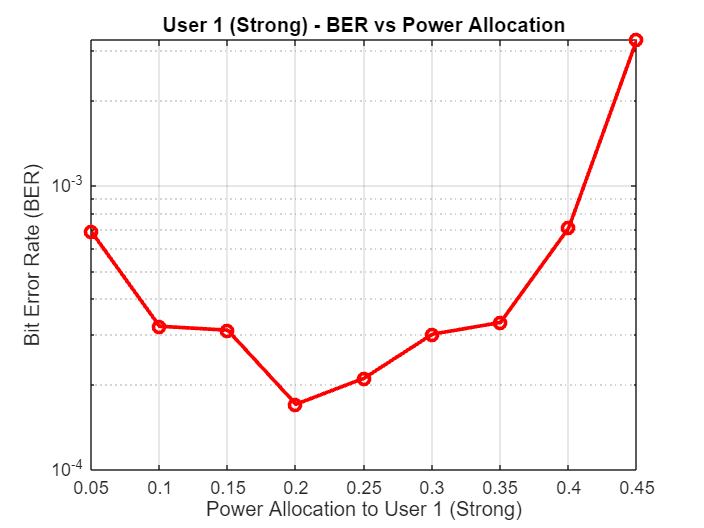



%% Separate Plots for BER vs Power Allocation


% BER vs Power Allocation for User 1 (Strong)
figure;
semilogy(alpha1_vals, ber1_vals, 'r-o', 'LineWidth', 2);
grid on;
xlabel('Power Allocation to User 1 (Strong)');
ylabel('Bit Error Rate (BER)');
title('User 1 (Strong) - BER vs Power Allocation');

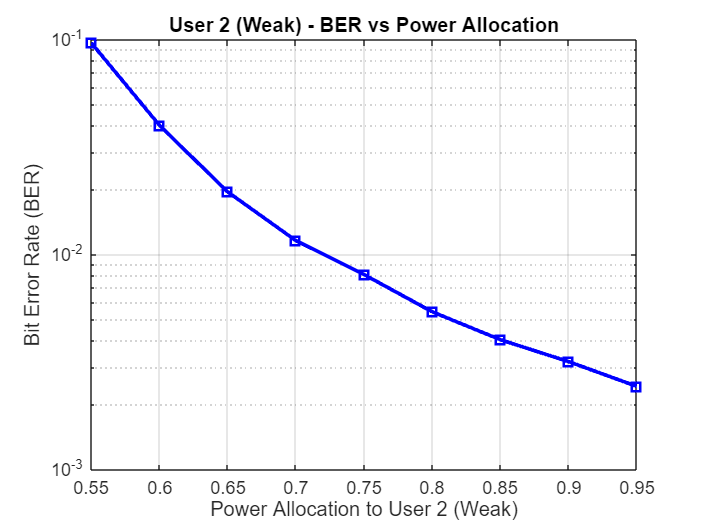



% BER vs Power Allocation for User 2 (Weak)
figure;
semilogy(1 - alpha1_vals, ber2_vals, 'b-s', 'LineWidth', 2);
grid on;
xlabel('Power Allocation to User 2 (Weak)');
ylabel('Bit Error Rate (BER)');
title('User 2 (Weak) - BER vs Power Allocation');